# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 모원재**

**학번**** : 201710912**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

n1 = [-200:200];
x1 = 5*(cos(0.49*pi*n1) + cos(0.51*pi*n1));
Hf_1 = figure; set(Hf_1,'NumberTitle','off','Name','P0201e');
Hs = stem(n1,x1,'filled'); set(Hs,'markersize',2);
axis([min(n1)-10,max(n1)+10,min(x1)-2,max(x1)+2]);

2) 

n2 = [0:100]; 
x2 = exp(-0.05*n2).*sin(0.1*pi*n2 + pi/3);
Hf_1 = figure; set(Hf_1,'NumberTitle','off','Name','P0201g');
Hs = stem(n2,x2,'filled'); set(Hs,'markersize',2);
axis([min(n2)-5,max(n2)+5,min(x2)-1,max(x2)+1]);

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

b = [1 2 0 1]; a = [1 -0.5 0.25]; [delta,n] = impz(b,a);
h = filter(b,a,delta);
Hf_1 = figure; set(Hf_1,'NumberTitle','off','Name','P0219a');
Hs = stem(n,h,'filled'); set(Hs,'markersize',2);
axis([min(n)-5,max(n)+5,min(h)-0.5,max(h)+0.5]);


2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

발산하지 않고 0에 수렴하므로 안정적이다.


3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

b = [1 2 0 1]; a = [1 -0.5 0.25]; n = 0:200;
x = 5*ones(size(n))+3*cos(0.2*pi*n)+4*sin(0.6*pi*n);
y = filter(b,a,x);
Hf_1 = figure; set(Hf_1,'NumberTitle','off','Name','P0219c');
Hs = stem(n,y,'filled'); set(Hs,'markersize',2);
axis([-10,210,0,50]);


3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

clc; close all;
n = [0:50]; x = 0.8.^n; h = (-0.9).^n;
Hf_1 = figure; set(Hf_1,'NumberTitle','off','Name','P0216');
y1 = ((0.8).^(n+1) - (-0.9).^(n+1))/(0.8+0.9);
subplot(1,3,1);
Hs1 = stem(n,y1,'filled');
set(Hs1,'markersize',2);


2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

x2 = x(1:26); h2 = h(1:26); y2 = conv(h2,x2);
subplot(1,3,2);
Hs2 = stem(n,y2,'filled'); 
set(Hs2,'markersize',2);


3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

y3 = filter([1],[1,0.9],x);
subplot(1,3,3);
Hs3 = stem(n,y3,'filled');
set(Hs3,'markersize',2);




4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

k = [-1000:1000];
w = (pi/1000)*k;
h = 0.9.^abs(n);
H = h*(exp(-i*pi/1000)).^(n'*k);
MagH = abs(H);
subplot(2,1,1);
plot(w/pi, MagH);
grid;
title('Magnitude Response');
AngH = angle(H);
subplot(2,1,2);
plot(w/pi, AngH);
grid;
title('Phase Response');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

t = [-1000:1:1000]*pi/500;
H = 1./(1-0.5*exp(-i*w))+1./(1-0.4*exp(-i*w));
MagH = abs(H);
subplot(2,1,1);
plot(w/pi,MagH);
grid;
title('Magnitude Response');
AngH = angle(H);
subplot(2,1,2);
plot(w/pi,AngH);
grid;
title('Phase Response');

5. (P3.17) 

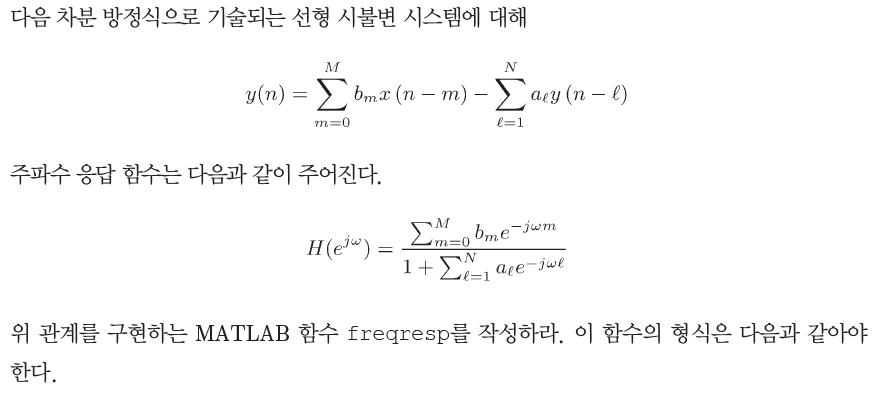

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

b = reshape(b,1,length(b));
a = reshape(a,1,length(a));
w = reshape(w,1,length(w));
m = 0:length(b)-1; num = b*exp(-i*m'*w);
l = 0:length(a)-1; den = a*exp(-i*l'*w);
H = num./den;

end

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$